# complex fo

## Fourier Series Calculator


syms t n T

assume(n,{'positive','integer'})
assume(T,{'positive'})

f=heaviside(t+T/4)-heaviside(t-T/4)  %initial func

$$f = \mathrm{heaviside}\left(\frac{T}{4}+t\right)-\mathrm{heaviside}\left(t-\frac{T}{4}\right)$$

interval=[-T/2,T/2]  %%func interval

$$interval = \left(\begin{array}{cc} -\frac{T}{2} & \frac{T}{2} \end{array}\right)$$


T_range=interval(2)-interval(1)  %time period

$$T\_range = T$$


theta=2*pi*t/T_range  %%theta

$$theta = \frac{2\,\pi \,t}{T}$$



C_n=1/T_range*simplify(int(f*exp(-j*theta*n),interval))

$$C\_n = \frac{{\left(-1\right)}^{n/2}\,\left(\frac{{\left(-1\right)}^{n}\,\mathrm{i}}{2}-\frac{1}{2}\,\mathrm{i}\right)}{n\,\pi }$$


for i=1:20
    C1_set(1,i)=sym(subs(C_n,n,i))*exp(j*theta*i);
    C2_set(1,i)=sym(subs(C_n,n,-i))*exp(-j*theta*i);
end

DC=int(f,t,interval)/T_range

$$DC = \frac{1}{2}$$

C2_set

$$C2\_set = \left(\begin{array}{cccccccccccccccccccc} \frac{{\mathrm{e}}^{-\frac{2\,\pi \,t\,\mathrm{i}}{T}}}{\pi } & 0 & -\frac{{\mathrm{e}}^{-\frac{6\,\pi \,t\,\mathrm{i}}{T}}}{3\,\pi } & 0 & \frac{{\mathrm{e}}^{-\frac{10\,\pi \,t\,\mathrm{i}}{T}}}{5\,\pi } & 0 & -\frac{{\mathrm{e}}^{-\frac{14\,\pi \,t\,\mathrm{i}}{T}}}{7\,\pi } & 0 & \frac{{\mathrm{e}}^{-\frac{18\,\pi \,t\,\mathrm{i}}{T}}}{9\,\pi } & 0 & -\frac{{\mathrm{e}}^{-\frac{22\,\pi \,t\,\mathrm{i}}{T}}}{11\,\pi } & 0 & \frac{{\mathrm{e}}^{-\frac{26\,\pi \,t\,\mathrm{i}}{T}}}{13\,\pi } & 0 & -\frac{{\mathrm{e}}^{-\frac{30\,\pi \,t\,\mathrm{i}}{T}}}{15\,\pi } & 0 & \frac{{\mathrm{e}}^{-\frac{34\,\pi \,t\,\mathrm{i}}{T}}}{17\,\pi } & 0 & -\frac{{\mathrm{e}}^{-\frac{38\,\pi \,t\,\mathrm{i}}{T}}}{19\,\pi } & 0 \end{array}\right)$$

C1_set

$$C1\_set = \left(\begin{array}{cccccccccccccccccccc} \frac{{\mathrm{e}}^{\frac{2\,\pi \,t\,\mathrm{i}}{T}}}{\pi } & 0 & -\frac{{\mathrm{e}}^{\frac{6\,\pi \,t\,\mathrm{i}}{T}}}{3\,\pi } & 0 & \frac{{\mathrm{e}}^{\frac{10\,\pi \,t\,\mathrm{i}}{T}}}{5\,\pi } & 0 & -\frac{{\mathrm{e}}^{\frac{14\,\pi \,t\,\mathrm{i}}{T}}}{7\,\pi } & 0 & \frac{{\mathrm{e}}^{\frac{18\,\pi \,t\,\mathrm{i}}{T}}}{9\,\pi } & 0 & -\frac{{\mathrm{e}}^{\frac{22\,\pi \,t\,\mathrm{i}}{T}}}{11\,\pi } & 0 & \frac{{\mathrm{e}}^{\frac{26\,\pi \,t\,\mathrm{i}}{T}}}{13\,\pi } & 0 & -\frac{{\mathrm{e}}^{\frac{30\,\pi \,t\,\mathrm{i}}{T}}}{15\,\pi } & 0 & \frac{{\mathrm{e}}^{\frac{34\,\pi \,t\,\mathrm{i}}{T}}}{17\,\pi } & 0 & -\frac{{\mathrm{e}}^{\frac{38\,\pi \,t\,\mathrm{i}}{T}}}{19\,\pi } & 0 \end{array}\right)$$


f2=simplify(DC)+sum(C1_set)+sum(C2_set)

$$f2 = \begin{array}{l} \frac{{\mathrm{e}}^{-\sigma_{10}}}{\pi }+\frac{{\mathrm{e}}^{\sigma_{10}}}{\pi }-\frac{{\mathrm{e}}^{-\sigma_{9}}}{3\,\pi }-\frac{{\mathrm{e}}^{\sigma_{9}}}{3\,\pi }+\frac{{\mathrm{e}}^{-\sigma_{8}}}{5\,\pi }+\frac{{\mathrm{e}}^{\sigma_{8}}}{5\,\pi }-\frac{{\mathrm{e}}^{-\sigma_{7}}}{7\,\pi }-\frac{{\mathrm{e}}^{\sigma_{7}}}{7\,\pi }+\frac{{\mathrm{e}}^{-\sigma_{6}}}{9\,\pi }+\frac{{\mathrm{e}}^{\sigma_{6}}}{9\,\pi }-\frac{{\mathrm{e}}^{-\sigma_{5}}}{11\,\pi }-\frac{{\mathrm{e}}^{\sigma_{5}}}{11\,\pi }+\frac{{\mathrm{e}}^{-\sigma_{4}}}{13\,\pi }+\frac{{\mathrm{e}}^{\sigma_{4}}}{13\,\pi }-\frac{{\mathrm{e}}^{-\sigma_{3}}}{15\,\pi }-\frac{{\mathrm{e}}^{\sigma_{3}}}{15\,\pi }+\frac{{\mathrm{e}}^{-\sigma_{2}}}{17\,\pi }+\frac{{\mathrm{e}}^{\sigma_{2}}}{17\,\pi }-\frac{{\mathrm{e}}^{-\sigma_{1}}}{19\,\pi }-\frac{{\mathrm{e}}^{\sigma_{1}}}{19\,\pi }+\frac{1}{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{38\,\pi \,t\,\mathrm{i}}{T}\\ \sigma_{2}=\frac{34\,\pi \,t\,\mathrm{i}}{T}\\ \sigma_{3}=\frac{30\,\pi \,t\,\mathrm{i}}{T}\\ \sigma_{4}=\frac{26\,\pi \,t\,\mathrm{i}}{T}\\ \sigma_{5}=\frac{22\,\pi \,t\,\mathrm{i}}{T}\\ \sigma_{6}=\frac{18\,\pi \,t\,\mathrm{i}}{T}\\ \sigma_{7}=\frac{14\,\pi \,t\,\mathrm{i}}{T}\\ \sigma_{8}=\frac{10\,\pi \,t\,\mathrm{i}}{T}\\ \sigma_{9}=\frac{6\,\pi \,t\,\mathrm{i}}{T}\\ \sigma_{10}=\frac{2\,\pi \,t\,\mathrm{i}}{T} \end{array}$$


f_0=subs(f,T,1)

$$f\_0 = \mathrm{heaviside}\left(t+\frac{1}{4}\right)-\mathrm{heaviside}\left(t-\frac{1}{4}\right)$$

int_1=double(subs(interval,T,1))

int_1 =    -0.5000    0.5000


fplot(f_0,int_1)

hold on 

f_1=subs(f2,T,1)

$$f\_1 = \frac{{\mathrm{e}}^{-2\,\pi \,t\,\mathrm{i}}}{\pi }+\frac{{\mathrm{e}}^{2\,\pi \,t\,\mathrm{i}}}{\pi }-\frac{{\mathrm{e}}^{-6\,\pi \,t\,\mathrm{i}}}{3\,\pi }-\frac{{\mathrm{e}}^{6\,\pi \,t\,\mathrm{i}}}{3\,\pi }+\frac{{\mathrm{e}}^{-10\,\pi \,t\,\mathrm{i}}}{5\,\pi }+\frac{{\mathrm{e}}^{10\,\pi \,t\,\mathrm{i}}}{5\,\pi }-\frac{{\mathrm{e}}^{-14\,\pi \,t\,\mathrm{i}}}{7\,\pi }-\frac{{\mathrm{e}}^{14\,\pi \,t\,\mathrm{i}}}{7\,\pi }+\frac{{\mathrm{e}}^{-18\,\pi \,t\,\mathrm{i}}}{9\,\pi }+\frac{{\mathrm{e}}^{18\,\pi \,t\,\mathrm{i}}}{9\,\pi }-\frac{{\mathrm{e}}^{-22\,\pi \,t\,\mathrm{i}}}{11\,\pi }-\frac{{\mathrm{e}}^{22\,\pi \,t\,\mathrm{i}}}{11\,\pi }+\frac{{\mathrm{e}}^{-26\,\pi \,t\,\mathrm{i}}}{13\,\pi }+\frac{{\mathrm{e}}^{26\,\pi \,t\,\mathrm{i}}}{13\,\pi }-\frac{{\mathrm{e}}^{-30\,\pi \,t\,\mathrm{i}}}{15\,\pi }-\frac{{\mathrm{e}}^{30\,\pi \,t\,\mathrm{i}}}{15\,\pi }+\frac{{\mathrm{e}}^{-34\,\pi \,t\,\mathrm{i}}}{17\,\pi }+\frac{{\mathrm{e}}^{34\,\pi \,t\,\mathrm{i}}}{17\,\pi }-\frac{{\mathrm{e}}^{-38\,\pi \,t\,\mathrm{i}}}{19\,\pi }-\frac{{\mathrm{e}}^{38\,\pi \,t\,\mathrm{i}}}{19\,\pi }+\frac{1}{2}$$

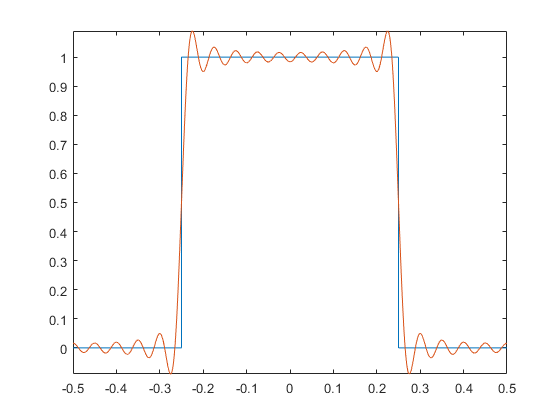

fplot(f_1,int_1)